## 0) Preparation

Get sample images from FLIR thermal dataset

clear; clc;clf;
% sample number
sn = 30;

% Local FLIR sample images
flir_dir = '.\FLIR-samples\';
if ~exist(flir_dir, "dir")
    mkdir(flir_dir);    
end

% List all local sample images
ir_imgs = dir(flir_dir);

% If the number is insufficient, resample from the source 
% FLIR thermal datasets
if length(ir_imgs)<sn
    % FLIR thermal dataset file path
    FLIR_ROOT = 'E:\FLIR_ADAS_1_3\train\thermal_8_bit\';
    imgs = dir(FLIR_ROOT);
    assert(length(imgs)>3);
    % random sampling
    ir_imgs = randsample(imgs(3:end),sn);
    
    % Copy to local save directory
    delete([flir_dir '*.jpeg']);
    
    for i=1:sn    
        copyfile([FLIR_ROOT ir_imgs(i).name],flir_dir);
    end
end


## 1) Randomly select an IR image for testing

clear; clc;clf;
% repeat sample folder, no need to execute the previous cell
flir_dir = '.\FLIR-samples\';
ir_imgs = dir(flir_dir);

% local random test, speed performance evaluation
% img = randsample(ir_imgs(3:end), 1);
img = ir_imgs(6);
I = im2double(imread([flir_dir, img.name]));
disp('Stylized Edge Extraction:')

Stylized Edge Extraction:


tic;
seog = stylized_edge_og(I,2);
toc;

历时 0.148030 秒。


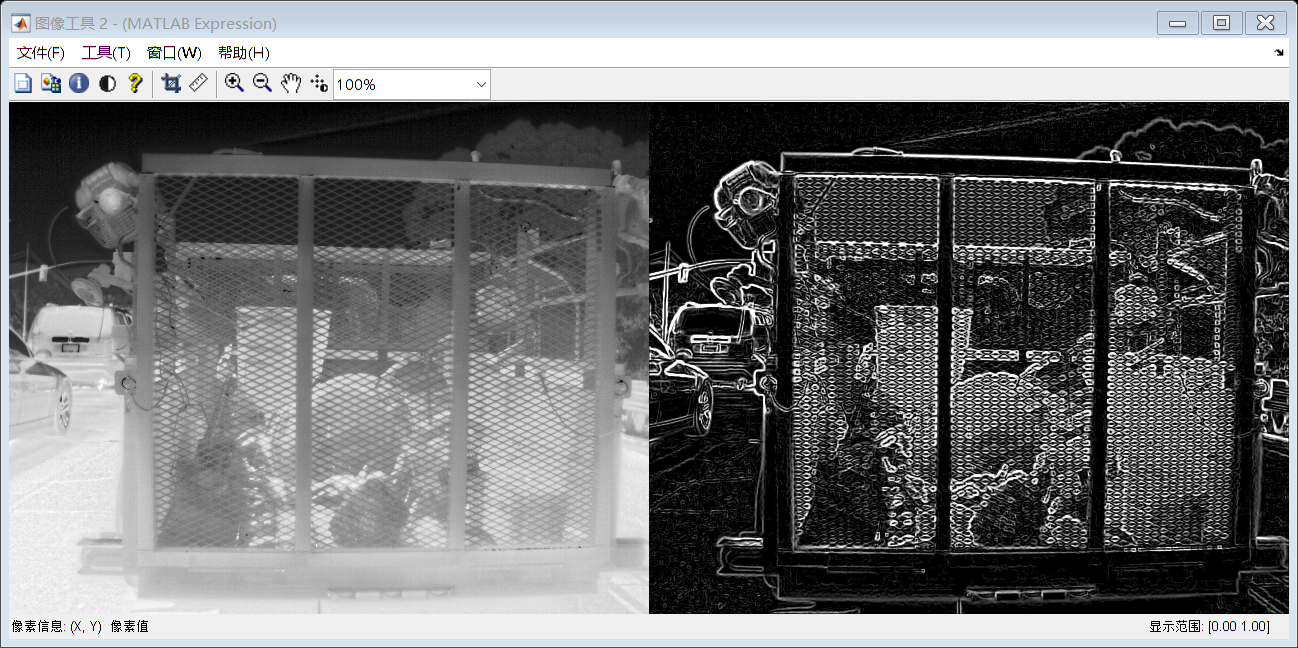

imtool([I seog]);

## 2) Process all sample images and count the average execution time

clear; clc;clf;
% repeat sample folder, no need to execute the previous cell
flir_dir = '.\FLIR-samples\';
ir_imgs = dir(flir_dir);
N = length(ir_imgs);

se_dir = '.\FLIR-stylized-edges\';
if ~exist(se_dir, "dir")
    mkdir(se_dir);    
end
delete([se_dir '*.jpeg']);

t = zeros(1,N-2);
for i=3:N
    I = im2double(imread([flir_dir, ir_imgs(i).name]));
    tic;
    seog = stylized_edge_og(I,2);
    t(i-2) = toc;
    % Save result image
    imwrite(seog, [se_dir 'se-' ir_imgs(i).name]);
end

% Average time
tm = sum(t)/(N-2);
disp(['Average time of ', num2str(N-2), ' images:', num2str(tm)]);

Average time of 30 images:0.11277


## 3) Compared to classical edge extraction methods

% Generate the images for `Fig.5` in the article

demo_img = 'Fig5_a.png';
I = im2double(rgb2gray(imread(demo_img)));
es = stylized_edge_og(I,3);

% save folder
save_dir = '.\Fig5\';
if ~exist(save_dir, "dir")
    mkdir(save_dir);
end
delete([save_dir '*.png']);

imwrite(I, [save_dir 'Fig5_a.png']);

ec1 = edge(I,'Canny', [0.02,0.05]);
imwrite(ec1, [save_dir 'Fig5_b.png']);
ec2 = edge(I,'Canny',[0.01 0.03]);
imwrite(ec2, [save_dir 'Fig5_c.png']);

ec3 = edge(I, 'Sobel', 0.01);
imwrite(ec3, [save_dir 'Fig5_d.png']);

ec4 = edge(I, 'Prewitt', 0.01);
imwrite(ec4, [save_dir 'Fig5_e.png']);

ec5 = edge(I, 'Roberts', 0.01);
imwrite(ec5, [save_dir 'Fig5_f.png']);

imwrite(es, [save_dir 'Fig5_g.png']);